# Leloup-Goldbeter Model

# Parameters

53 original

+1 for LD

+11 for full

%% Parameters, 54 in total
p = struct();
p.k_1 = 0.4;
p.k_2 = 0.2;
p.k_3 = 0.4;
p.k_4 = 0.2;
p.k_5 = 0.4;
p.k_6 = 0.2;
p.k_7 = 0.5;
p.k_8 = 0.1;
p.K_AP = 0.7;
p.K_AC = 0.6;
p.K_IB = 2.2;
p.k_dmb = 0.01;
p.k_dmc = 0.01;
p.k_dmp = 0.01;
p.k_dn = 0.01;
p.k_dnc = 0.12;
p.K_d = 0.3;
p.K_dp = 0.1;
p.K_p = 0.1;
p.K_mB = 0.4;
p.K_mC = 0.4;
p.K_mP = 0.31;
p.k_sB = 0.12;
p.k_sC = 1.6;
p.k_sP = 0.6;
p.m = 2;
p.n = 4;
p.V_1B = 0.5;
p.V_1C = 0.6;
p.V_1P = 0.4;
p.V_1PC = 0.4;
p.V_2B = 0.1;
p.V_2C = 0.1;
p.V_2P = 0.3;
p.V_2PC = 0.1;
p.V_3B = 0.5;
p.V_3PC = 0.4;
p.V_4B = 0.2;
p.V_4PC = 0.1;
p.V_phos = 0.4;
p.v_dBC = 0.5;
p.v_dBN = 0.6;
p.v_dCC = 0.7;
p.v_dIN = 0.8;
p.v_dPC = 0.7;
p.v_dPCC = 0.7;
p.v_dPCN = 0.7;
p.v_mB = 0.8;
p.v_mC = 1.0;
p.v_mP = 1.1;
p.v_sB = 1.0;
p.v_sC = 1.1;
p.v_sP = 1.5;
p.v_sPmax = 1.8; % for light

p_fields = {'k_1', 'k_2', 'k_3', 'k_4', 'k_5', 'k_6', 'k_7', 'k_8', ...
              'K_AP', 'K_AC', 'K_IB', 'k_dmb', 'k_dmc', 'k_dmp', 'k_dn', 'k_dnc', ...
              'K_d', 'K_dp', 'K_p', 'K_mB', 'K_mC', 'K_mP', 'k_sB', 'k_sC', ...
              'k_sP', 'm', 'n', 'V_1B', 'V_1C', 'V_1P', 'V_1PC', 'V_2B', ...
              'V_2C', 'V_2P', 'V_2PC', 'V_3B', 'V_3PC', 'V_4B', 'V_4PC', 'V_phos', ...
              'v_dBC', 'v_dBN', 'v_dCC', 'v_dIN', 'v_dPC', 'v_dPCC', 'v_dPCN', ...
              'v_mB', 'v_mC', 'v_mP', 'v_sB', 'v_sC', 'v_sP', 'v_sPmax'};

p_array = zeros(length(p_fields), 1);

for i = 1:length(p_fields)
    p_array(i) = p.(p_fields{i});
end

# y: 16 vars

y = struct();
y.M_P = 1.5;
y.M_C = 1.3;
y.M_B = 3.3;

y.P_C = 0;
y.C_C = 0;
y.P_CP = 0;
y.C_CP = 0;

y.PC_C = 0;
y.PC_N = 0;
y.PC_CP = 0;
y.PC_NP = 0;

y.B_C = 0;
y.B_CP = 0;
y.B_N = 0;
y.B_NP = 0;

y.I_N = 0;

y_fields = {'M_P', 'M_C', 'M_B', 'P_C', 'C_C', 'P_CP', 'C_CP', ...
            'PC_C', 'PC_N', 'PC_CP', 'PC_NP', 'B_C', 'B_CP', 'B_N', 'B_NP', 'I_N'};

y_array = zeros(length(y_fields), 1);

for i = 1:length(y_fields)
    y_array(i) = y.(y_fields{i});
end

# Options

tspan = [0 480];
options = odeset('RelTol',1e-8,'AbsTol',1e-10);

# DD模拟

[t1, y1] = ode45(@LG, tspan, y_array, options, p_array);

# 绘图，最后72小时（3天）

P_tot, C_tot, B_tot

delay = 72

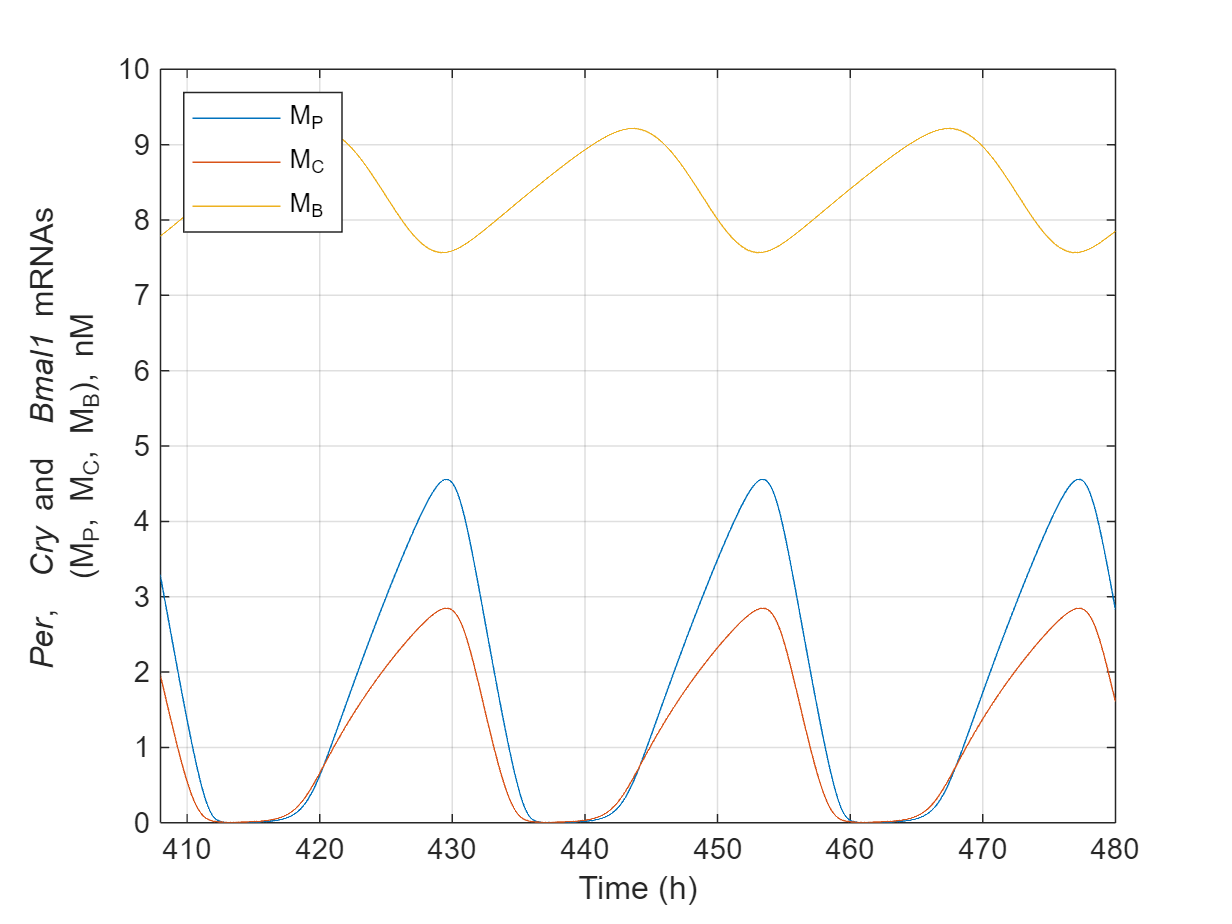

delay = 72;

M_P = y1(:, 1);
M_C = y1(:, 2);
M_B = y1(:, 3);

% 计算总蛋白质含量
% P_tot = 所有含PER的蛋白质
P_tot = y1(:, 4) + y1(:, 6) + y1(:, 8) + y1(:, 9) + y1(:, 10) + y1(:, 11);  % P_C + P_CP + PC_C + PC_N + PC_CP + PC_NP

% C_tot = 所有含CRY的蛋白质
C_tot = y1(:, 5) + y1(:, 7) + y1(:, 8) + y1(:, 9) + y1(:, 10) + y1(:, 11);  % C_C + C_CP + PC_C + PC_N + PC_CP + PC_NP

% B_tot = 所有含BMAL1的蛋白质
B_tot = y1(:, 12) + y1(:, 13) + y1(:, 14) + y1(:, 15);  % B_C + B_CP + B_N + B_NP

figure;
plot(t1, M_P, t1, M_C, t1, M_B);
xlabel('Time (h)');
ylabel({'{\it Per}, {\it Cry} and {\it Bmal1} mRNAs', '(M_P, M_C, M_B), nM'});
legend('M_P', 'M_C', 'M_B', 'Location', 'northwest');
xlim([t1(end)-delay, t1(end)]);
grid on;

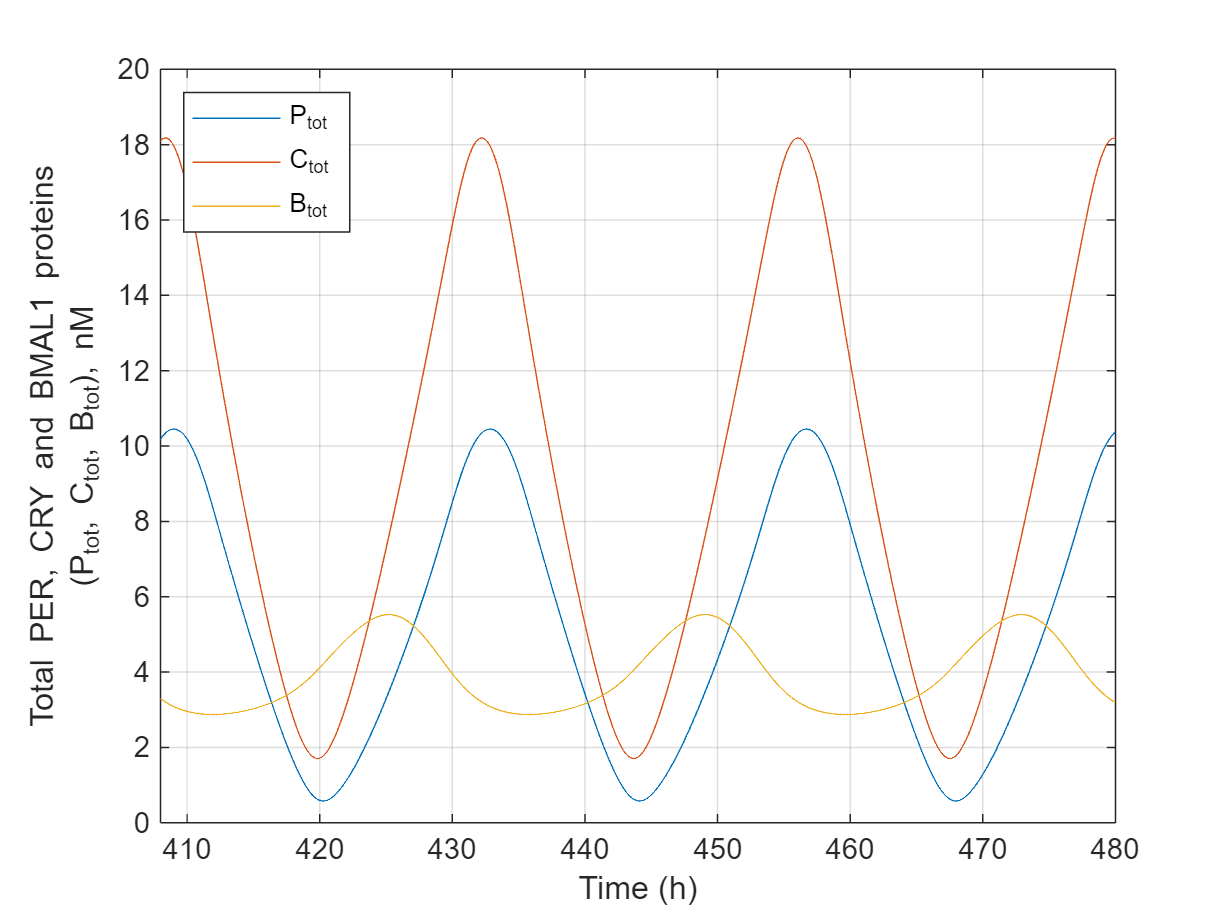


figure;
plot(t1, P_tot, t1, C_tot, t1, B_tot);
xlabel('Time (h)');
ylabel({'Total PER, CRY and BMAL1 proteins', '(P_{tot}, C_{tot}, B_{tot}), nM'});
legend('P_{tot}', 'C_{tot}', 'B_{tot}', 'Location', 'northwest');
xlim([t1(end)-delay, t1(end)]);
grid on;

# 使用峰值测量Per mRNA周期

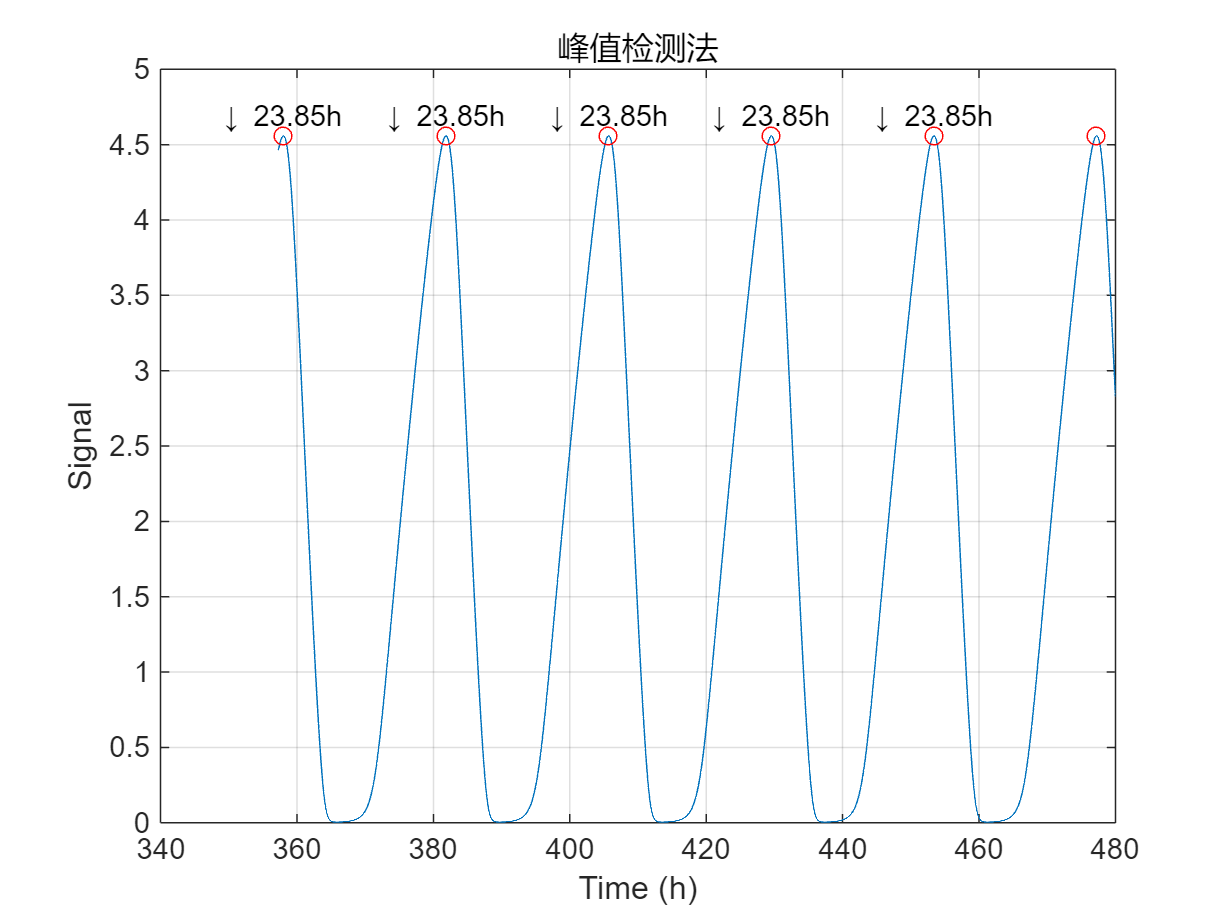

峰值检测结果：平均振荡周期为 23.85 小时


t_signal = t1;
signal = y1(:,1);

period_peak(t_signal, signal);

# LD模拟

[t2, y2] = ode45(@LG_light, tspan, y_array, options, p_array);

# 绘图

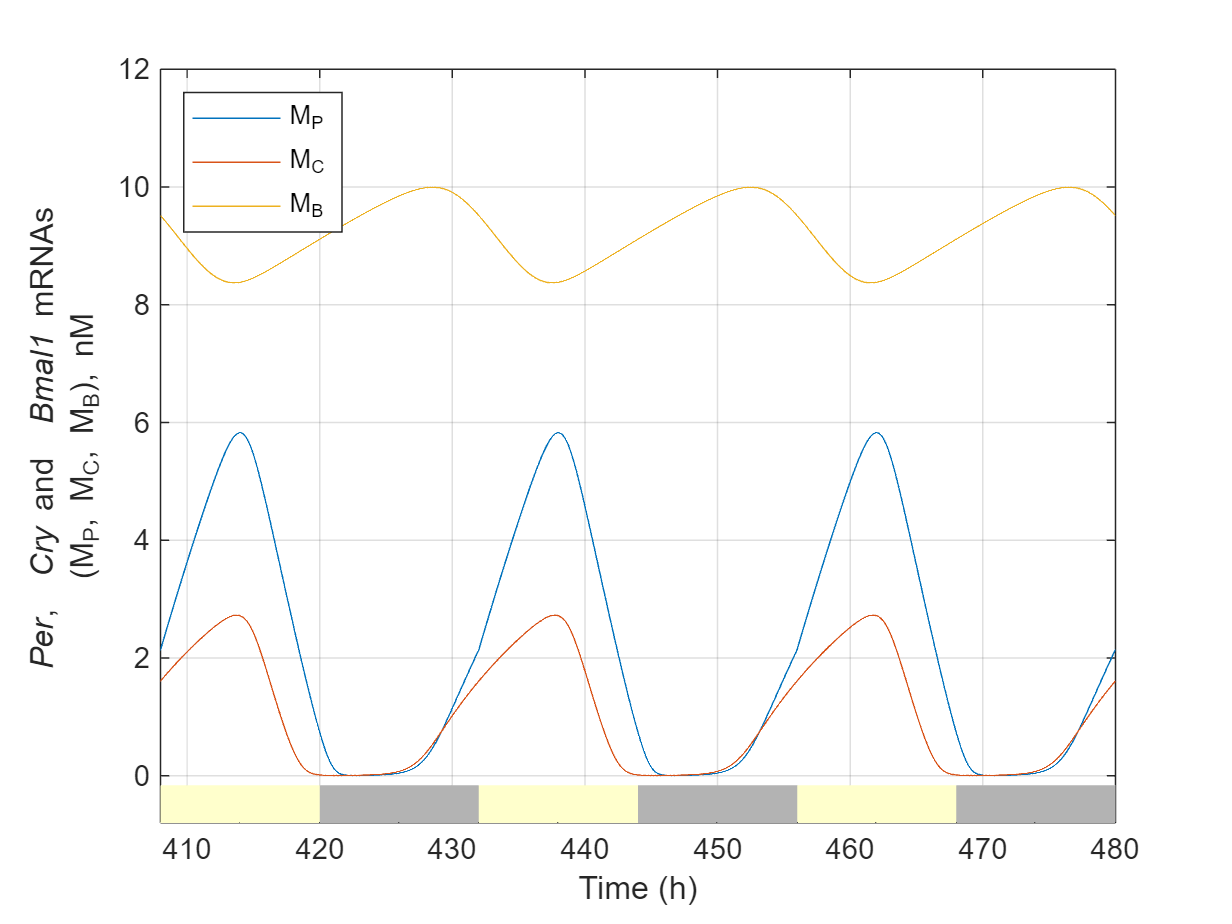

figure;
plot(t2, y2(:, 1:3));
xlabel('Time (h)');
ylabel({'{\it Per}, {\it Cry} and {\it Bmal1} mRNAs', '(M_P, M_C, M_B), nM'});
legend('M_P', 'M_C', 'M_B', 'Location', 'northwest');
xlim([t2(end)-delay, t2(end)]);
ylim([-0.8 12]);
grid on;

% Get current axis limits
ax = gca;
ylims = ylim;
ypos = ylims(1) - 0.05*(ylims(2)-ylims(1)); % Position slightly below the plot

% Add light-dark indicators
start_time = t2(end)-delay;
end_time = t2(end);
for t = ceil(start_time/24)*24:24:end_time
    % Light phase (white or light yellow rectangle)
    rectangle('Position', [t, ypos, 12, 0.1*(ylims(2)-ylims(1))], ...
              'FaceColor', [1 1 0.8], 'EdgeColor', 'none');
    % Dark phase (gray rectangle)
    rectangle('Position', [t+12, ypos, 12, 0.1*(ylims(2)-ylims(1))], ...
              'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'none');
end

# 测量LD周期

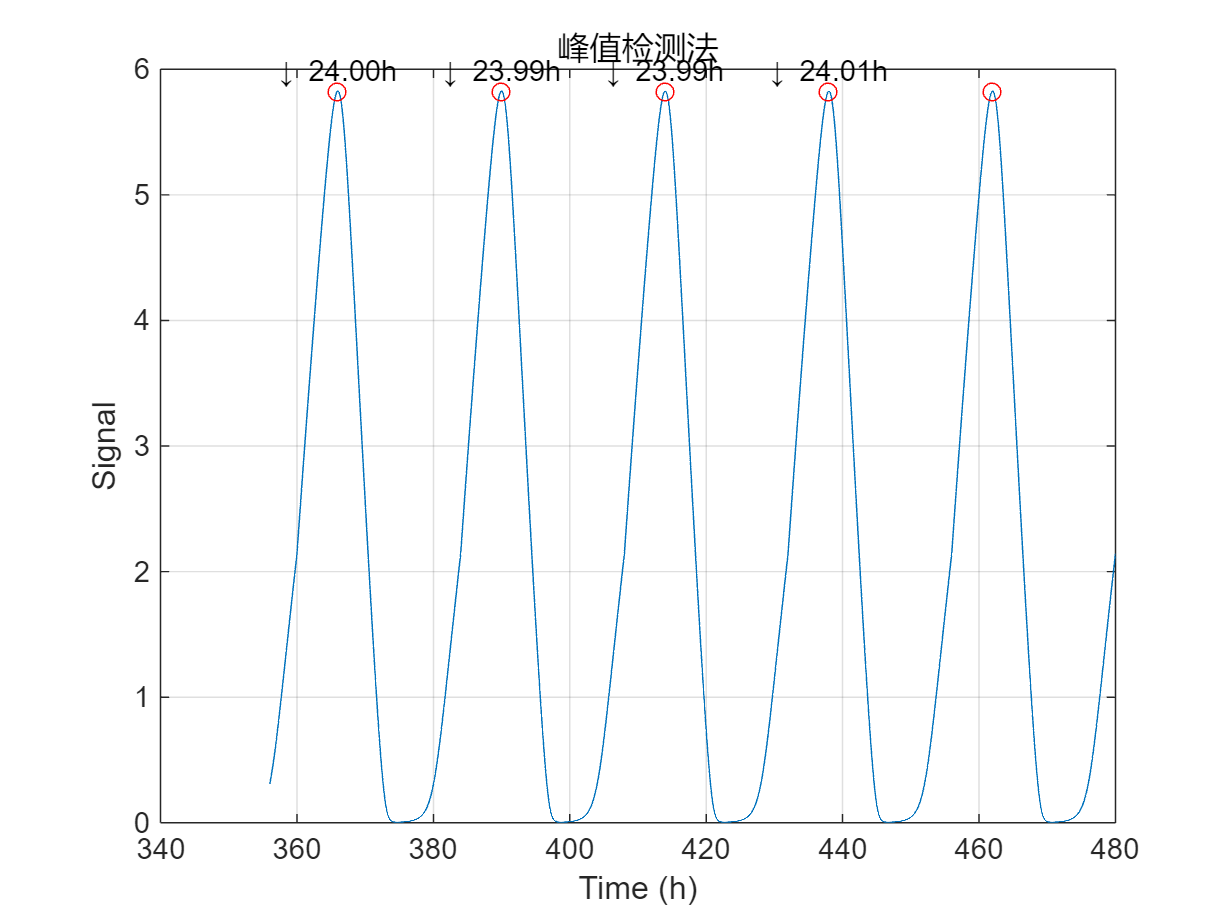

峰值检测结果：平均振荡周期为 24.00 小时


t_signal = t2;
signal = y2(:,1);

period_peak(t_signal, signal);

# 修改参数：K_AC从0.6变为0.4nM

p_array(10) = 0.4;

# DD模拟

[t3, y3] = ode45(@LG, tspan, y_array, options, p_array);

# 测量DD周期

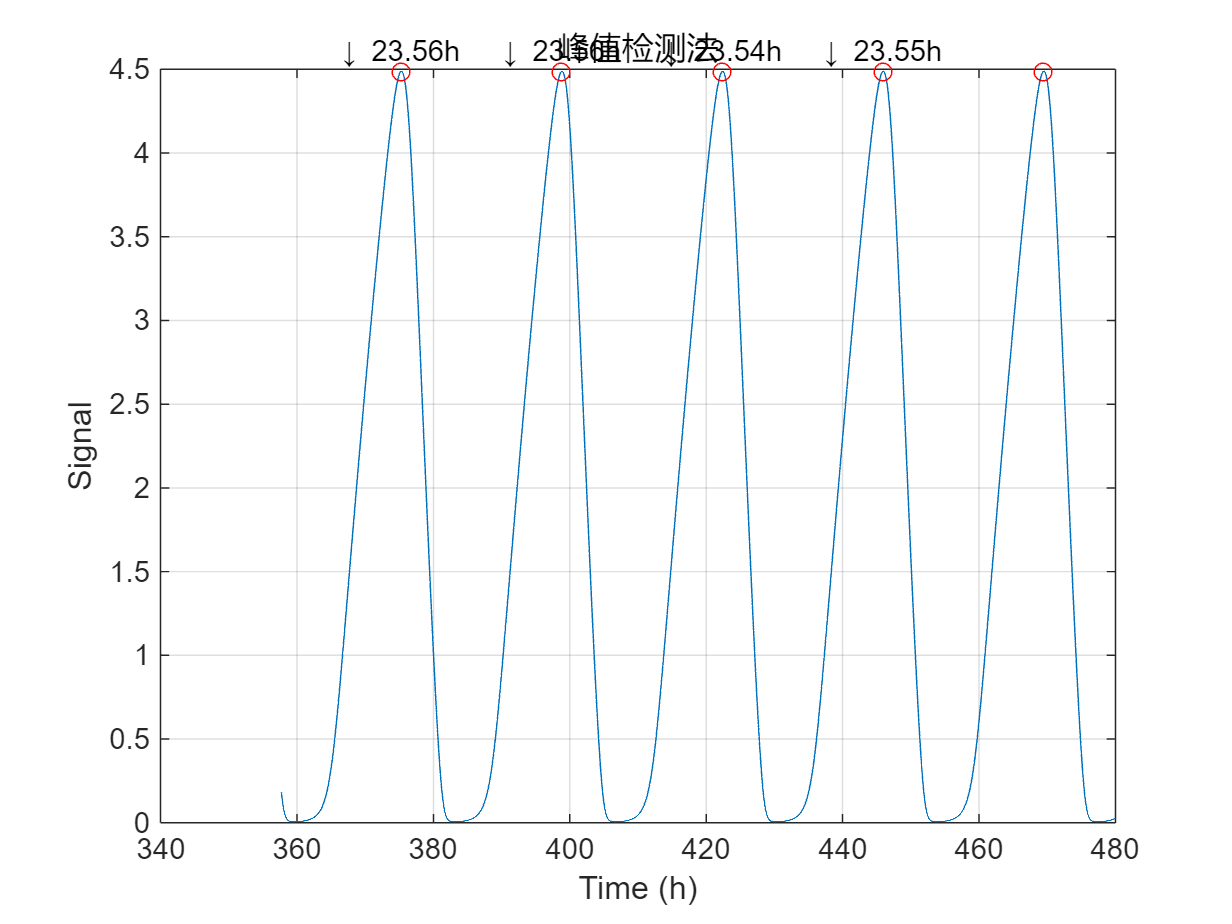

峰值检测结果：平均振荡周期为 23.55 小时


t_signal = t3;
signal = y3(:,1);

period_peak(t_signal, signal);

# LD模拟

[t4, y4] = ode45(@LG_light, tspan, y_array, options, p_array);

# 绘图

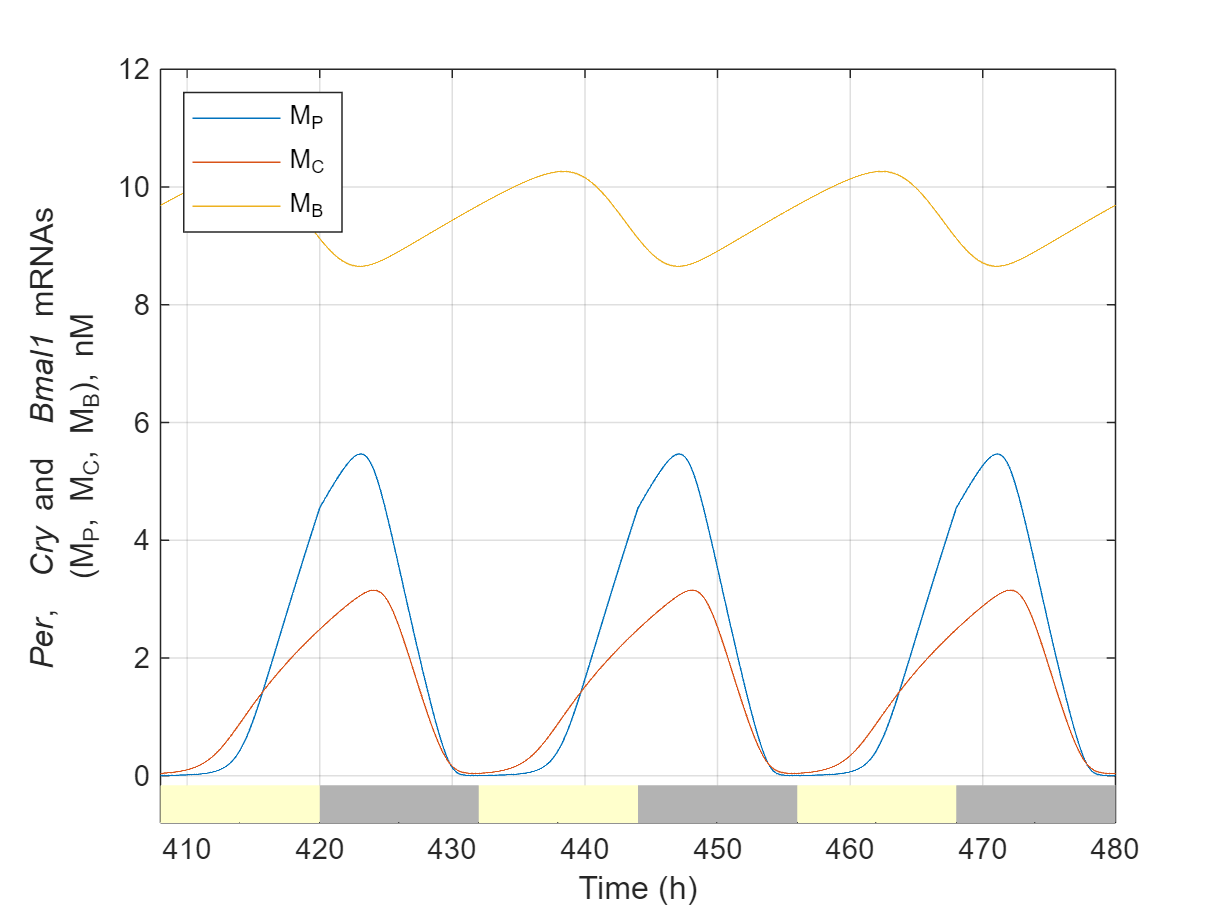

figure;
plot(t4, y4(:, 1:3));
xlabel('Time (h)');
ylabel({'{\it Per}, {\it Cry} and {\it Bmal1} mRNAs', '(M_P, M_C, M_B), nM'});
legend('M_P', 'M_C', 'M_B', 'Location', 'northwest');
xlim([t4(end)-delay, t4(end)]);
ylim([-0.8 12]);
grid on;

% Get current axis limits
ax = gca;
ylims = ylim;
ypos = ylims(1) - 0.05*(ylims(2)-ylims(1)); % Position slightly below the plot

% Add light-dark indicators
start_time = t4(end)-delay;
end_time = t4(end);
for t = ceil(start_time/24)*24:24:end_time
    % Light phase (white or light yellow rectangle)
    rectangle('Position', [t, ypos, 12, 0.1*(ylims(2)-ylims(1))], ...
              'FaceColor', [1 1 0.8], 'EdgeColor', 'none');
    % Dark phase (gray rectangle)
    rectangle('Position', [t+12, ypos, 12, 0.1*(ylims(2)-ylims(1))], ...
              'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'none');
end

# 测量LD周期

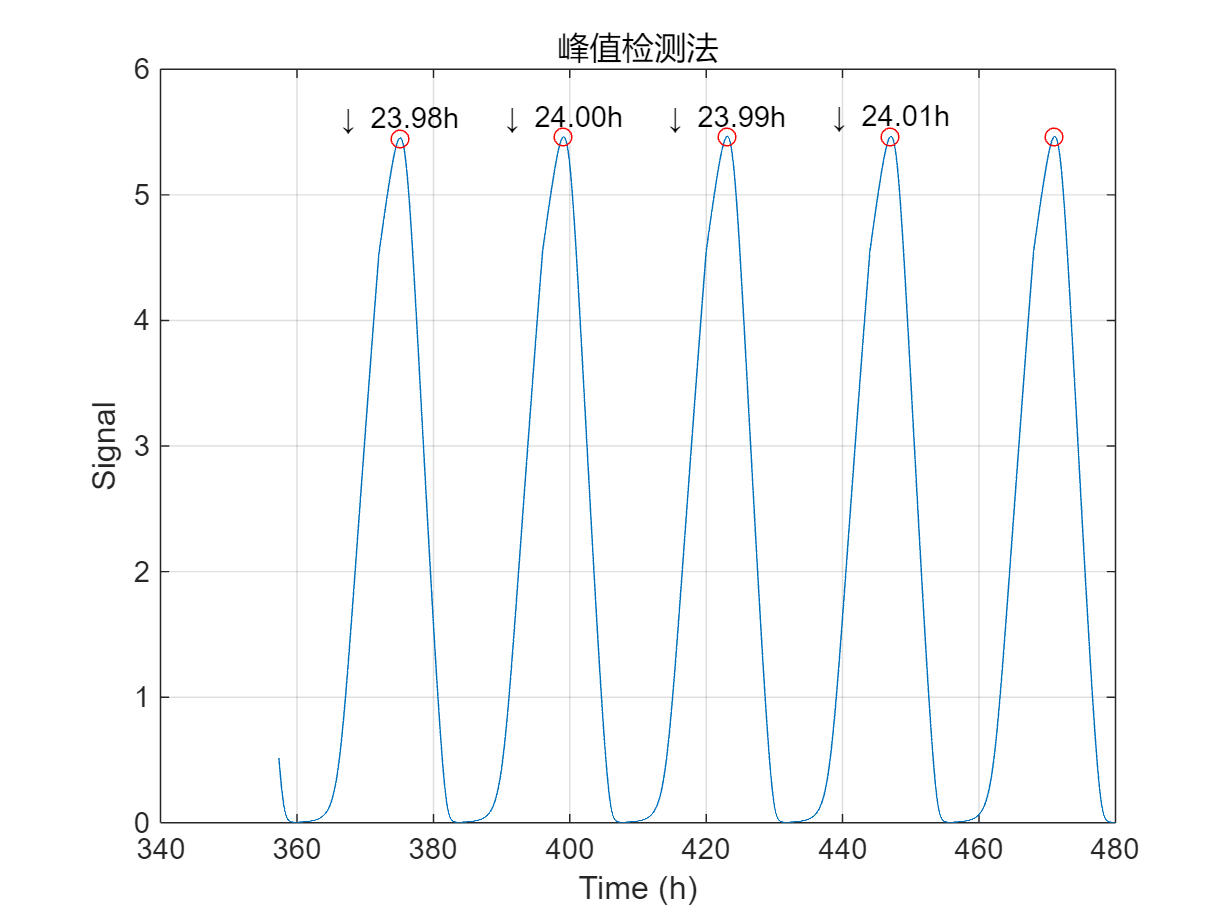

峰值检测结果：平均振荡周期为 23.99 小时


t_signal = t4;
signal = y4(:,1);

period_peak(t_signal, signal);